# Gaussian stocastic simulation with area-to-point kriging (A2PK)

This script show you how to generate stocastic fine-scale realization conditioned to a coarse-scale image using area-to-point kriging and conditioning kriging.

addpath('../functions');

## Generation of the synthetic data

- The covariance model (`covar`) is built with its type (`model`), range (range0), variance (`c0`) and azimuth (`azimuth`). 

covar.model='exponential'; covar.range0=[20 20]; covar.c0=1;covar.azimuth=0;
covar= kriginginitiaite(covar);

- The fine-scale grid size is defined with z`.x and z.y`

z.x=1:100;
z.y=1:100;
[z.X,z.Y] = meshgrid(z.x, z.y);
z.nxy =numel(z.X);
z.nx=numel(z.x);
z.ny=numel(z.y);

- FFT-MA [10.1023/A:1007542406333](http://dx.doi.org/10.1023/A:1007542406333) is used to generate the Gaussian field (`fftma_perso()`)

z.true = fftma_perso(covar, z);

- The coarse scale grid size is defined as a factor of the fine scale (Z`.dx, Z.dy`)

Z.dx=5; Z.dy=5;
Z.x = Z.dx/2:Z.dx:z.x(end);
Z.y = Z.dy/2:Z.dy:z.y(end);
[Z.X,Z.Y] = meshgrid(Z.x, Z.y);

- Built the matrix G which link the coarse scale to the fine scale. We define it here as a nearest-neighbors average.

G = zeros(numel(Z.X),z.nxy);
for ij=1:z.nxy
     [~,id_z]=min((z.X(ij)-Z.X(:)).^2 + (z.Y(ij)-Z.Y(:)).^2);
     G(id_z,ij)=1;
     %G(id_z,ij)=1/(Z.dx*Z.dy); % make it proportional to the cell size if not regular grid.
end
for ij = 1:numel(Z.X)
    G(ij,G(ij,:)==1) = 1 ./ sum(G(ij,:)==1);
end

- Compute coarse scale d

Z.true = reshape(G * z.true(:), numel(Z.y), numel(Z.x));

## Plot

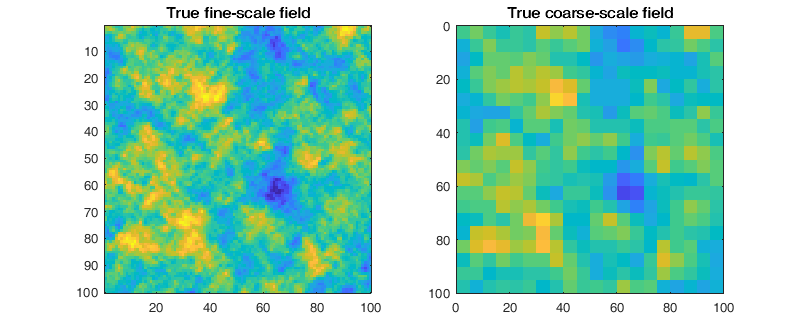

c_axis=[ min(z.true(:)) max(z.true(:))]; 
figure('pos',[0 0 800 330])
subplot(1,2,1);imagesc(z.x, z.y, z.true); caxis(c_axis); title('True fine-scale field'); axis equal;
subplot(1,2,2);imagesc(Z.x, Z.y, Z.true); caxis(c_axis); title('True coarse-scale field'); axis equal;

## Kriging prediction

- Build the covariance of the fine-scale

Czz = covar.g(squareform(pdist([z.X(:) z.Y(:)]*covar.cx)));

- Build the cross-covariance

CzZ = Czz * G';

- Build the covariance of the coarse scale

CZZ = G * CzZ;

- Compute the kriging weight

W=zeros(z.nxy,numel(Z.X));
for ij=1:z.nxy
    W(ij,:) = CZZ \ CzZ(ij,:)';
end

- Compute the kriging estimation map

z.krig = reshape( W * Z.true(:), z.ny,z.nx);

## Plot

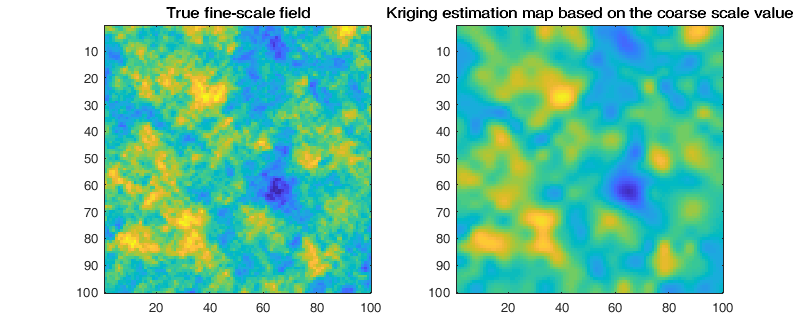

imagesc(z.x, z.y, z.krig); caxis(c_axis); title('Kriging estimation map based on the coarse scale value'); axis equal;

## Generate conditional realization

- Produce unconditional simulation

z.uncondSim = fftma_perso(covar, z);

- Built the corresponding coarse-scale

Z.uncondSim = reshape(G * z.uncondSim(:), numel(Z.y), numel(Z.x));

- Compute the kriging map of the unconditional simulation

z.krigSim = reshape( W * Z.uncondSim(:), z.ny,z.nx);

- Build condtional realization with conditionin kriging

z.condSim = z.krig + (z.uncondSim - z.krigSim);

- Compute the coarse scale of the conditional realization 

Z.condSim = reshape(G * z.condSim(:), numel(Z.y), numel(Z.x));

## Plot

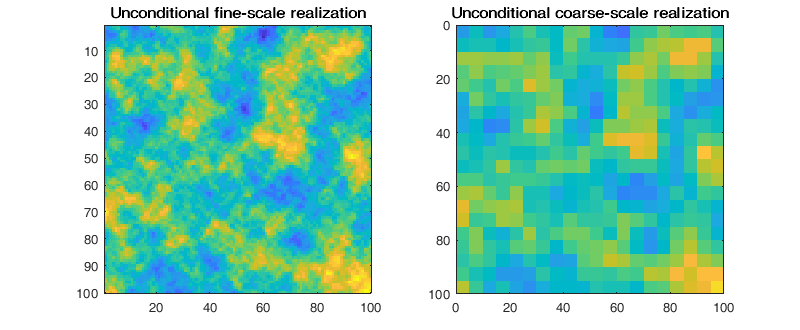

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(z.x, z.y, z.uncondSim); caxis(c_axis); title('Unconditional fine-scale realization');
subplot(1,2,2); imagesc(Z.x, Z.y, Z.uncondSim); caxis(c_axis); title('Unconditional coarse-scale realization');

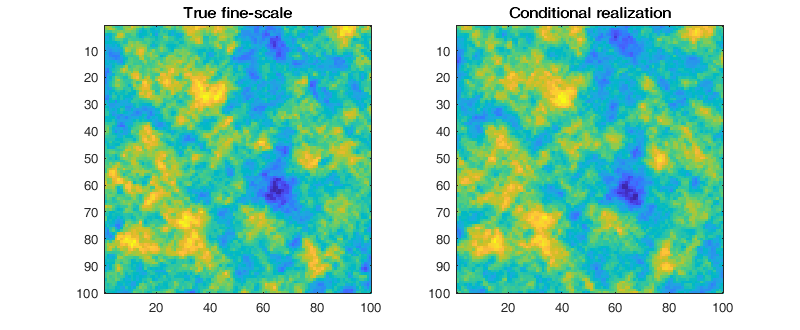

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(z.x, z.y, z.true); caxis(c_axis); title('True fine-scale');
subplot(1,2,2);imagesc(z.x, z.y, z.condSim); caxis(c_axis); title('Conditional realization');

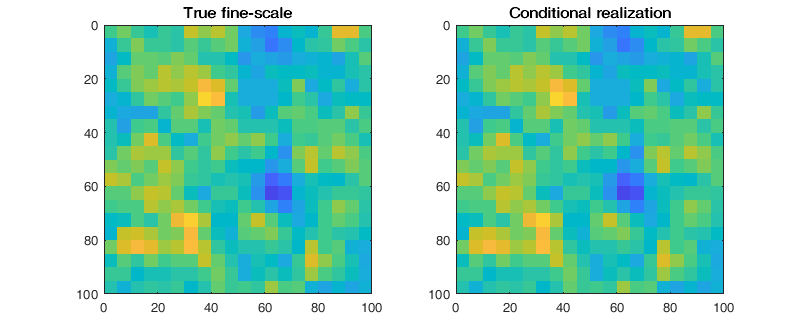

figure('pos',[0 0 800 330])
subplot(1,2,1); imagesc(Z.x, Z.y, Z.true); caxis(c_axis); title('True fine-scale');
subplot(1,2,2);imagesc(Z.x, Z.y, Z.condSim); caxis(c_axis); title('Conditional realization');

## Analysis of the realization

- Histogram and Variogram

*TO BE DONE*